% ----------------------------
% Example: FIR + Manual Hamming Window
% ----------------------------

% (1) Simulate noisy data
fs    = 1000;                      % sampling frequency (Hz)
t     = 0:1/fs:1;                  % 1 s vector
s     = sin(2*pi*50*t) + 0.5*sin(2*pi*120*t);
noise = 0.3*randn(size(t));
x     = s + noise;                 % noisy signal

% (2) FIR low‑pass design parameters
fc = 100;                          % cutoff (Hz)
wc = 2*pi*fc/fs;                   % normalized (rad/sample)
L  = 61;                           % filter length (odd for symmetry)
M  = (L-1)/2;
n  = 0:L-1;

% (3) Ideal impulse response (sinc), truncated
hd = sin(wc*(n-M)) ./ (pi*(n-M));
hd(M+1) = wc/pi;                   % n = M case

% (4) Manually compute Hamming window
%    W[n] = a – b*cos(2πn/(L-1)) + c*cos(4πn/(L-1))
a = 0.54;  b = 0.46;  c = 0;       % Hamming coefficients
w = a - b*cos(2*pi*n/(L-1)) + c*cos(4*pi*n/(L-1));

% (5) Windowed FIR coefficients
b = hd .* w;

% (6) Normalize to unity DC gain
b = b / sum(b);

% (7) Filter and separate
y         = filter(b, 1, x);      % filtered (≈ clean)
est_noise = x - y;                 % noise estimate

% (8) Plot results
figure;
subplot(3,1,1)
plot(t, x),   title('Noisy Signal'),    xlabel('Time (s)')
subplot(3,1,2)
plot(t, y),   title('Filtered Signal'), xlabel('Time (s)')
subplot(3,1,3)
plot(t, est_noise), title('Estimated Noise'), xlabel('Time (s)')

% (9) Show filter response
[H,f] = freqz(b,1,1024,fs);
figure;
plot(f,20*log10(abs(H)))
grid on
title('FIR Magnitude Response')
xlabel('Freq (Hz)'), ylabel('Magnitude (dB)')

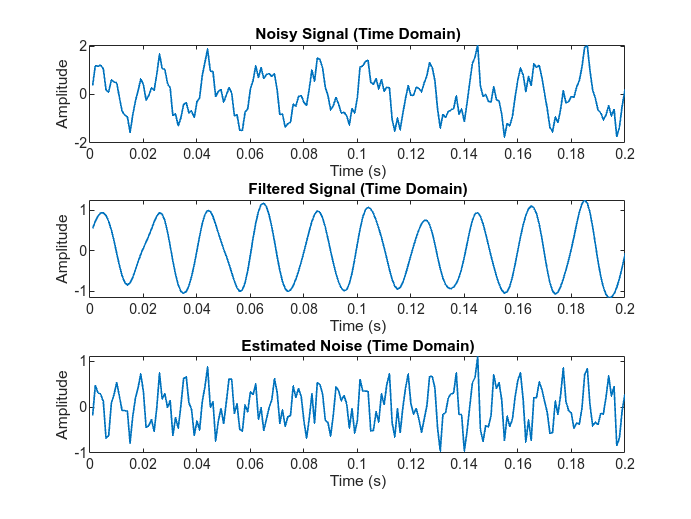

% ----------------------------
% Lab‑Style Noise Separation (Zoomed Time + Full Frequency)
% ----------------------------
clear; clc; close all;

% (1) Simulate “true” data + additive noise
fs    = 1000;            % sampling rate (Hz)
tmax  = 3;               % duration (s)
dt    = 1/fs;
t     = dt:dt:tmax;      
N     = length(t);

% — example “clean” signal (two tones)
clean = sin(2*pi*50*t) + 0.5*sin(2*pi*120*t);
% — AWGN
x     = clean + 0.3*randn(size(t));  

% (2) Design low‑pass FIR via manual Hanning window
fc      = 100;                  % cutoff freq (Hz)
omega_c = 2*pi*fc/fs;           
L       = 51;                   
M       = (L-1)/2;              
n       = 0:(L-1);

% 2.1 ideal sinc impulse response (truncated) :contentReference[oaicite:0]{index=0}​:contentReference[oaicite:1]{index=1}
h_ideal = sin(omega_c*(n-M)) ./ (pi*(n-M));
h_ideal(M+1) = omega_c/pi;      

% 2.2 Hanning window: w[n] = 0.5 – 0.5*cos(2πn/(L–1)) :contentReference[oaicite:2]{index=2}​:contentReference[oaicite:3]{index=3}
w = 0.5 - 0.5*cos(2*pi*n/(L-1));           

% 2.3 windowed FIR kernel
h = h_ideal .* w;                             

% (3) Filter via convolution and separate noise
y     = conv(x, h, 'same');    % filtered (≈ clean data)
noise = x - y;                 % estimated noise

% (4) Time‑domain plots (zoomed into first 0.2 s)
figure('Name','Time‑Domain Signals (Zoomed)','NumberTitle','off');
subplot(3,1,1);
plot(t, x, 'LineWidth',1);
xlim([0 0.2]);
title('Noisy Signal (Time Domain)');
xlabel('Time (s)'); ylabel('Amplitude');

subplot(3,1,2);
plot(t, y, 'LineWidth',1);
xlim([0 0.2]);
title('Filtered Signal (Time Domain)');
xlabel('Time (s)'); ylabel('Amplitude');

subplot(3,1,3);
plot(t, noise, 'LineWidth',1);
xlim([0 0.2]);
title('Estimated Noise (Time Domain)');
xlabel('Time (s)'); ylabel('Amplitude');

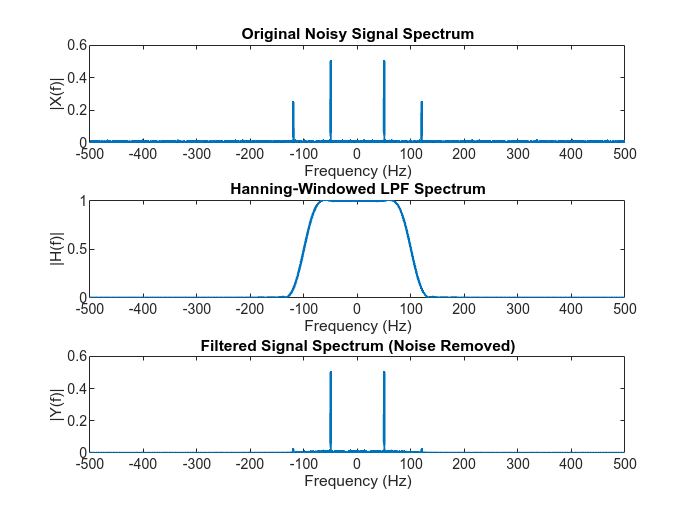


% (5) Frequency‑domain analysis
X = fftshift(fft(x))/N;
Y = fftshift(fft(y))/N;
H = fftshift(fft(h, N))/sum(h);
freq = linspace(-fs/2, fs/2, N);

figure('Name','Frequency‑Domain Analysis','NumberTitle','off');
subplot(3,1,1);
plot(freq, abs(X), 'LineWidth',1.5);
xlim([-500 500]);
title('Original Noisy Signal Spectrum');
xlabel('Frequency (Hz)'); ylabel('|X(f)|');

subplot(3,1,2);
plot(freq, abs(H), 'LineWidth',1.5);
xlim([-500 500]);
title('Hanning‑Windowed LPF Spectrum');
xlabel('Frequency (Hz)'); ylabel('|H(f)|');

subplot(3,1,3);
plot(freq, abs(Y), 'LineWidth',1.5);
xlim([-500 500]);
title('Filtered Signal Spectrum (Noise Removed)');
xlabel('Frequency (Hz)'); ylabel('|Y(f)|');